# AMR Project

% clear all;

### Simulation Init

connection = simulation_setup();

Running Matlab win64
make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


robotNb = 0;
connection = simulation_openConnection(connection, robotNb);
simulation_start(connection);

### Robot Init

[bodyDiameter wheelDiameter interWheelDist scannerPose] = bob_init(connection);
[bodyDiameter] = bob_getBodyDiameter(connection);
[wheelDiameter] = bob_getWheelDiameter(connection);
[interWheelDist] = bob_getInterWheelDistance(connection);
[scannerPose] = bob_getScannerPose(connection);

parameters.dist_threshold= 0.01; % threshold distance to goal
parameters.angle_threshold = 0.1; % threshold orientation to goal
parameters.wheelDiameter = bob_getWheelDiameter(connection);
parameters.wheelRadius = parameters.wheelDiameter/2.0;
parameters.interWheelDistance = bob_getInterWheelDistance(connection);
parameters.scannerPoseWrtBob = bob_getScannerPose(connection);

% controller parameters
parameters.Krho = 0.8;
parameters.Kalpha = 3;
parameters.Kbeta = -0.7;
% parameters.Krho = 1;
% parameters.Kalpha = 0.1;
% parameters.Kbeta = -0.1;
% parameters.Krho = 2.5; 
% parameters.Kalpha = 7.5;
% parameters.Kbeta = -1.5;
parameters.backwardAllowed = true;
parameters.useConstantSpeed = false;
% parameters.constantSpeed = 0.4;

bob_setTargetGhostVisible(connection, 1);
pause(0.5);

### Controller Setup

LeftEncoder = [];
RigthEncoder = [];
directionHistory = [];
vuHistory =[];
global activated;
activated = false;
global points;
points = 1000;
Data = DataRecord.Init();
Controller = PIDController.Init();
CTE = PIDController.PIDCrossTrackError(0.1, 0.1, 0.1);
Controller.timestamp = 0.01;
[Controller.center(1), Controller.center(2), Controller.center(3)] = bob_getPose(connection);
[xg, yg, thetag] = bob_getTargetGhostPose(connection);

### Cross-track Error(不用了)

CTE.Kp = 0;
CTE.Ki = 0;
CTE.Kd = 0;

### Path Calculation

distribution = linspace(0,2*pi,points);
% Circle
r = 2;
% Controller.pathplan(:,1) = Controller.center(1) + r*cos(distribution);
% Controller.pathplan(:,2) = Controller.center(2) + r*sin(distribution);
Controller.pathplan(:,1) = r*cos(distribution);
Controller.pathplan(:,2) = r*sin(distribution);
Controller.pathplan(:,3) = atan2(Controller.pathplan(:,1),-Controller.pathplan(:,2));
% Eight Number
% a = 2;
% Controller.pathplan(:,1) = sqrt(a) * cos(distribution) .* sin(distribution) ./ (1 + sin(distribution).^2);
% Controller.pathplan(:,2) = sqrt(a) * cos(distribution) ./ (1 + sin(distribution).^2);
% Controller.pathplan(:,3) = atan2(Controller.pathplan(:,1),-Controller.pathplan(:,2));
% Double Curve
% r = 2;
% delta_y = 0.5;
% Controller.pathplan(:,1) = r*cos(distribution);
% Controller.pathplan(:,2) = r*sin(distribution) + delta_y*sin(2*distribution);
% Controller.pathplan(:,3) = atan2(Controller.pathplan(:,1),-Controller.pathplan(:,2));
% Straight Line
% Controller.pathplan(:,1) = r*cos(distribution);
% Controller.pathplan(:,2) = r*sin(distribution) + delta_y*sin(2*distribution);
% Controller.pathplan(:,3) = atan2(Controller.pathplan(:,2),Controller.pathplan(:,1));
% for i = 1:points-1
%     bob_addPathSegment(connection,Controller.pathplan(i,1),Controller.pathplan(i,2),Controller.pathplan(i+1,1),Controller.pathplan(i+1,2));
%     pause(0.1);
% end
% DataRecord.threading(connection, Data);

### Close Loop Simulation

% [x_hitory, y_history, ~] = CloseLoopSimulation(Controller, parameters);
% figure(7);
% plot(x_history, y_history);

### Robot Task

EndCond = 0;
prev_error = 0;
prev_vu = 0;
prev_omega = 0;
sum_error = 0;
allow_points = 0;
CTE.ld = 0.3;
tic;
for i = 1:points
    activated = true;
    Data.time = [Data.time; toc];
    bob_setTargetGhostPose(connection, Controller.pathplan(i,1), Controller.pathplan(i,2), Controller.pathplan(i,3));
    EndCond = false;
    while (~EndCond)
        %% CONTROL STEP.
        % Get pose and goalPose from vrep
        [x, y, theta] = bob_getPose(connection);
        % [xg, yg, thetag] = bob_getTargetGhostPose(connection);
        if(i==1)
            xg = Controller.pathplan(i,1);
            yg = Controller.pathplan(i,2);
            thetag = Controller.pathplan(i,3);
        end
        directionHistory = [directionHistory; [xg-x yg-y]];
        
        allow_points = int32(points/5+4*i/5);
        if(i>0)
            [Controller,xg,yg,thetag,distance] = pointSelection(Controller,i,allow_points,CTE.ld,x,y,theta);
        end

        Data.TargetDistanceHistory = [Data.TargetDistanceHistory; distance(1:1)];
        
        % run control step
        [vu, omega, Controller, CTE, Data] = calculateControlOutput([x, y, theta], [xg, yg, thetag], prev_vu, prev_omega, parameters, Controller, CTE, Data);
        
        Data.VuHistory = [Data.VuHistory; vu];
        Data.OmegaHistory = [Data.OmegaHistory; omega];
        prev_vu = vu;
        prev_omega = omega;
        
        % Calculate wheel speeds
        [LeftWheelVelocity, RightWheelVelocity ] = calculateWheelSpeeds(vu, omega, parameters);
        
        % Encoder
        % [LE, RE] = bob_getEncoders(connection);
        % LeftEncoder = [LeftEncoder; LE];
        % RigthEncoder = [RigthEncoder; RE];
        
        % End condition
        dtheta = abs(normalizeAngle(theta-thetag));
        
        % rho = sqrt((xg-x)^2+(yg-y)^2);  % pythagoras theorem, sqrt(dx^2 + dy^2)
        rho = sqrt((Controller.pathplan(i,1)-x)^2+(Controller.pathplan(i,2)-y)^2);
        % EndCond = (rho < parameters.dist_threshold && dtheta < parameters.angle_threshold) || rho > 5;    
        EndCond = (rho < parameters.dist_threshold); 

        % SET ROBOT WHEEL SPEEDS.
        bob_setWheelSpeeds(connection, LeftWheelVelocity, RightWheelVelocity);
    
        % Data Record
        Data.radiusICR = [Data.radiusICR; (parameters.interWheelDistance/2)*(LeftWheelVelocity+RightWheelVelocity)/(LeftWheelVelocity-RightWheelVelocity)];
        ErrorVector = [xg-x, yg-y, thetag-theta];
        PoseErrorVector = [cos(theta), sin(theta), 0; -sin(theta), cos(theta), 0; 0, 0, 1]*ErrorVector';
        % Controller.curvature = [Controller.curvature; curvature];
        Data.ErrorVector = [Data.ErrorVector; ErrorVector];
        Data.PoseErrorVector = [Data.PoseErrorVector; PoseErrorVector'];
        Data.timeX = [Data.timeX; x];
        Data.timeY = [Data.timeY; y];
    
        pause(Controller.timestamp);
    end
    Data.measureX = [Data.measureX; x];
    Data.measureY = [Data.measureY; y];
end

### Data Recording

Data.trueX = Controller.pathplan(:,1);
Data.trueY = Controller.pathplan(:,2);
Data.error = sqrt((Data.trueX-Data.measureX).^2+(Data.trueY-Data.measureY).^2);
LeftOdometry = zeros(size(LeftEncoder));
RightOdometry = zeros(size(RigthEncoder));
LeftOdometry(:) = LeftEncoder(:)*parameters.wheelDiameter;
RightOdometry(:) = RigthEncoder(:)*parameters.wheelDiameter;

### Stop Simulation

simulation_setStepped(connection,false);
simulation_stop(connection);
simulation_closeConnection(connection);

### Plot Result

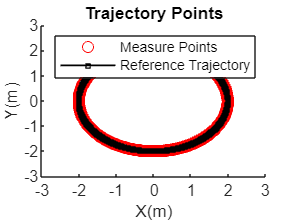

Data.error = sqrt((Data.trueX-Data.measureX).^2+(Data.trueY-Data.measureY).^2);
error_mean = mean(Data.error)*ones(size(Data.error));
delta = 0.1; % 調整切線向量的大小

savePath = '..\Result\';
clc;
% cla;
figure(1);
% quiver(Controller.pathplan(:,1), Controller.pathplan(:,2),-Controller.pathplan(:,2),Controller.pathplan(:,1), 'r');
% hold on;
scatter(Data.timeX, Data.timeY,'r','o');
hold on;
plot(Data.trueX, Data.trueY,'-s','MarkerSize',3,'Color','k','LineWidth',1);
xlim([-3 3]), ylim([-3 3]);
xticklabels(-3:1:3), yticklabels(-3:1:3);
xlabel('X(m)'), ylabel('Y(m)');
legend('Measure Points','Reference Trajectory');
title('Trajectory Points');
saveas(figure(1),strcat(savePath,'Trajectory_Points.png'));

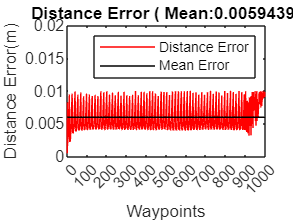


figure(2);
plot(0:points-1, Data.error,'r');
hold on;
plot(0:points-1, error_mean,'k');
txt = {'    \uparrow',strcat('Error Mean: ',string(error_mean(1)))};
% text(20,error_mean(1)*8/10,txt,'FontSize',12);
xticks2 = 0:int32(points/10):points;
xticks(xticks2);
xticklabels(string(int32(xticks2)));
xlabel('Waypoints'), ylabel('Distance Error(m)');
% xticklabels(0:round(Data.time(end)/100,1)*100);
% xlim([0 round(Data.time(end)/100,1)*100]);
ylim([0 0.02]);
legend('Distance Error', 'Mean Error');
title(strcat('Distance Error ( Mean:',string(error_mean(1)),')'));
saveas(figure(2),strcat(savePath,'Distance_Error.png'));

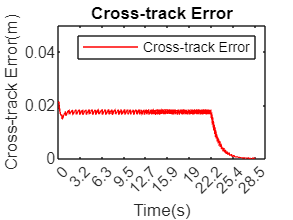


% figure(3);
% plot(1:size(Data.ErrorVector,1),Data.ErrorVector(:,1),'Color','r','LineStyle','-'); hold on;
% plot(1:size(Data.ErrorVector,1),Data.ErrorVector(:,2),'Color','#0072BD','LineStyle','-'); hold on;
% % plot(1:size(Data.ErrorVector,1),Data.ErrorVector(:,3),'Color','k','LineStyle','-'); hold on;
% legend("ErrorX","ErrorY");
% hold off;

figure(4);
plot(1:size(Data.CrossTrackError,1),Data.CrossTrackError(:,1),'Color','r','LineStyle','-');
xlabel('Time(s)'), ylabel('Cross-track Error(m)');
xticks4 = linspace(0,size(Data.CrossTrackError,1),10);
xticks(xticks4);
xticklabels(string(round(xticks4(:)*Controller.timestamp,1)));
ylim([0 0.05]);
legend('Cross-track Error');
title('Cross-track Error');
saveas(figure(4),strcat(savePath,'Crosstrack_Error.png'));

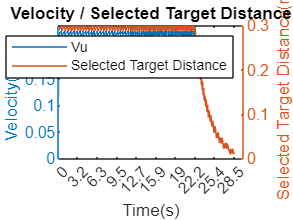


figure(5);
yyaxis left;
plot(1:size(Data.VuHistory,1),Data.VuHistory(:,1),'-');
xlabel('Time(s)'), ylabel('Velocity(m/s)');
xticks5 = linspace(0,size(Data.VuHistory,1),10);
xticks(xticks5);
xticklabels(string(round(xticks5(:)*Controller.timestamp,1)));
% ylim([0 0.5]);
hold on;
yyaxis right;
plot(1:size(Data.TargetDistanceHistory,1),Data.TargetDistanceHistory(:,1),'-');
ylabel('Selected Target Distance(m)');
ylim([0 CTE.ld]);
% hold on;
% plot(1:size(Data.TargetDistanceHistory,1),ld*ones(size(Data.TargetDistanceHistory,1)),'-','Color','k');
legend('Vu','Selected Target Distance');
title('Velocity / Selected Target Distance');
saveas(figure(5),strcat(savePath,'Velocity.png'));

% figure(6);
% plot(1:size(Data.curvature,1),Data.curvature(:,1),'Color','r','LineStyle','-');
% drawnow;